load fisheriris
X = meas(:,3:4);
Y = species;

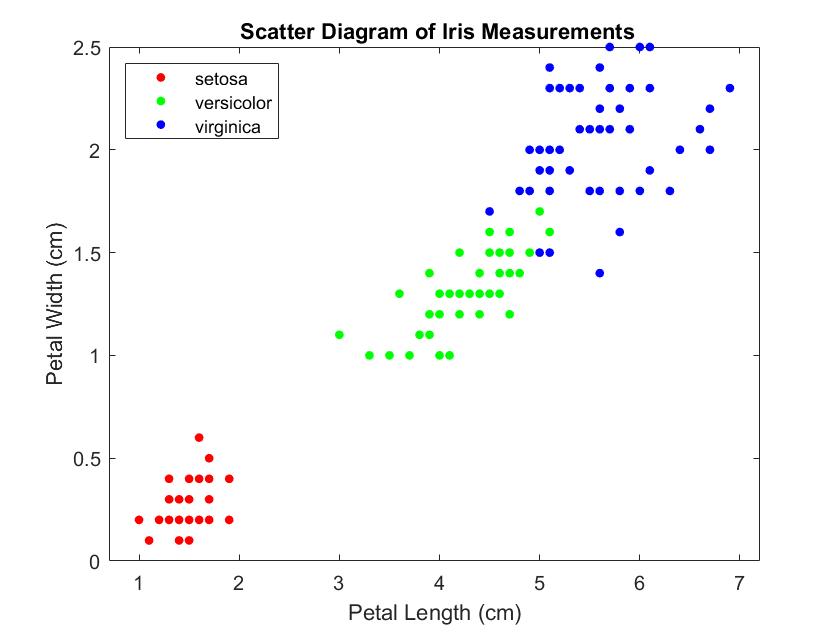

figure
gscatter(X(:,1),X(:,2),Y);
h = gca;
lims = [h.XLim h.YLim]; % Extract the x and y axis limits
title('{\bf Scatter Diagram of Iris Measurements}');
xlabel('Petal Length (cm)');
ylabel('Petal Width (cm)');
legend('Location','Northwest');

SVMModels = cell(3,1);
classes = unique(Y);
rng(1); % For reproducibility

for j = 1:numel(classes)
    indx = strcmp(Y,classes(j)); % Create binary classes for each classifier
    SVMModels{j} = fitcsvm(X,indx,'ClassNames',[false true],'Standardize',true,...
        'KernelFunction','rbf','BoxConstraint',1);
end

d = 0.02;
[x1Grid,x2Grid] = meshgrid(min(X(:,1)):d:max(X(:,1)),...
    min(X(:,2)):d:max(X(:,2)));
xGrid = [x1Grid(:),x2Grid(:)];
N = size(xGrid,1);
Scores = zeros(N,numel(classes));

for j = 1:numel(classes)
    [~,score] = predict(SVMModels{j},xGrid);
    Scores(:,j) = score(:,2); % Second column contains positive-class scores
end

figure
h(1:3) = gscatter(xGrid(:,1),xGrid(:,2),maxScore,...
    [0.1 0.5 0.5; 0.5 0.1 0.5; 0.5 0.5 0.1]);

Unrecognized function or variable 'maxScore'.

hold on
h(4:6) = gscatter(X(:,1),X(:,2),Y);
title('{\bf Iris Classification Regions}');
xlabel('Petal Length (cm)');
ylabel('Petal Width (cm)');
legend(h,{'setosa region','versicolor region','virginica region',...
    'observed setosa','observed versicolor','observed virginica'},...
    'Location','Northwest');
axis tight
hold off